addpath('scripts')
format long
clc
clear all
close all

enable_prints = true;

global sigma;
global filter_size;
global filter_padding_value;

sigma = 1.0;
filter_size = 101;
filter_padding_value =  0.0;

sigmas = [1.0 2.5 4.1 5.0];
filter_sizes = [5 41 45 101];
print_types = {{"-depsc", ".eps"}, {"-dpng", ".png"}};


## Wasserstein distance test

----------------


Meta: sigma = 1, filter_size = 5


#1: W2 = 456.5759, D2 = 0.064619, sum(\pi1) = 0.73738


#2: W2 = 1370.3567, D2 = 0.089501, sum(\pi1) = 1.3564e-299


#3: W2 = 1370.3567, D2 = 0.089501, sum(\pi1) = 1.3574e-299


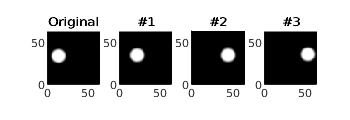

format long g


imgs = {
         im2double(rgb2gray(imread('images/one-blob.png')))
         im2double(rgb2gray(imread('images/one-blob-moved.png')))
         im2double(rgb2gray(imread('images/one-blob-moved-even-more.png')))
         im2double(rgb2gray(imread('images/one-blob-moved-even-more-again.png')))
};


for filter_size=filter_sizes
    for sigma=sigmas
        
        disp('----------------')
        disp("Meta: sigma = "+sigma+", filter_size = "+filter_size)
        
        dists = {
                make_dist(imgs{1}),
                make_dist(imgs{2}),
                make_dist(imgs{3}),
                make_dist(imgs{4})
            };
            
        FigH = figure('Position', [0, 0, 350, 120]);
        colormap('gray')
        
        subplot(1,4,1)
        hold on
        axis equal
        axis([0, 64, 0 ,64])
        imagesc(dists{1})
        title('Original')
        
        
        for i = 2:4
            [wd,v,w] = Sinkhorn(dists{1},dists{i});
            ed = sqrt(sum(  (dists{1}(:) - dists{i}(:)).^2  ));
            marg = SinkhornEvalR(v,w,ones(size(v,1),size(v,2)));
        %     wd
        
            disp("#"+(i-1)+": "+"W2 = " + wd + ", D2 = " + ed + ", sum(\pi1) = " + sum(marg(:)));
            subplot(1,4,i)
            hold on
            axis equal
            axis([0, 64, 0, 64])
            imagesc(dists{i})
            title("#"+(i-1))
        
        %     title("\pi1 = p. sum(\pi1) = " + sum(img(:)))
        %     title("W2 = " + wd + ", D2 = " + ed)
        
        end
        
        if enable_prints
            for type = print_types
                print("prints/delta-comparison-"+sigma+"-sigma-"+filter_size+"-filter-size"+type{1}{2},type{1}{1})
            end
        end

    end
end



disp('------------------------------')

------------------------------


disp('------------------------------')

------------------------------


disp('------------------------------')

------------------------------


## Coupling Test #1

-----------------------------


Meta: sigma = 1, filter_size = 5


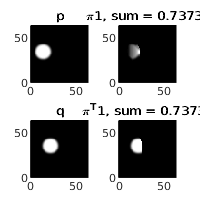

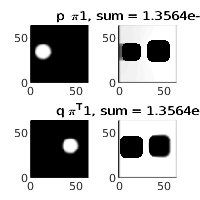

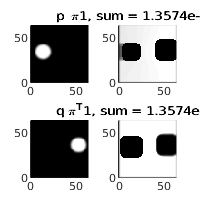

-----------------------------


Meta: sigma = 2.5, filter_size = 5


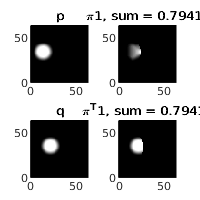

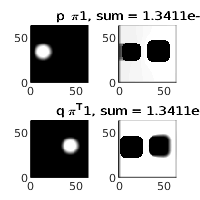

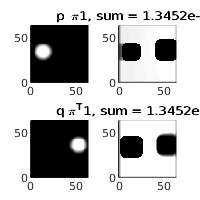

-----------------------------


Meta: sigma = 4.1, filter_size = 5


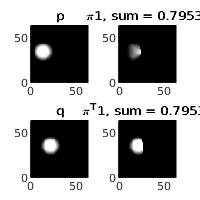

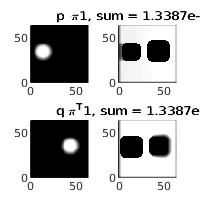

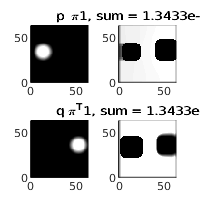

-----------------------------


Meta: sigma = 5, filter_size = 5


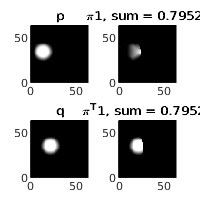

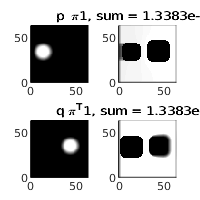

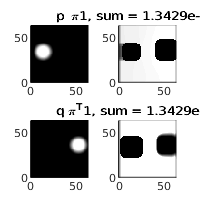

-----------------------------


Meta: sigma = 1, filter_size = 41


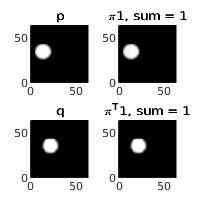

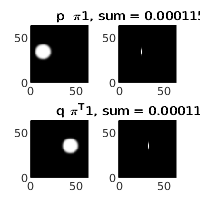

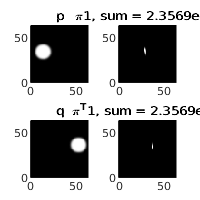

-----------------------------


Meta: sigma = 2.5, filter_size = 41


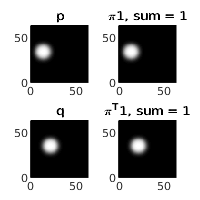

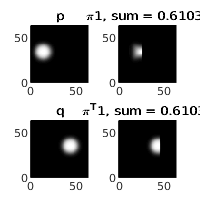

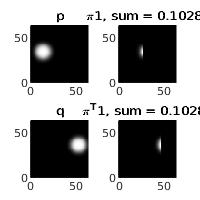

-----------------------------


Meta: sigma = 4.1, filter_size = 41


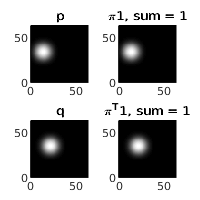

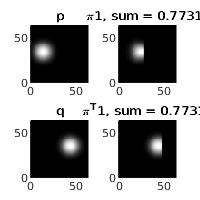

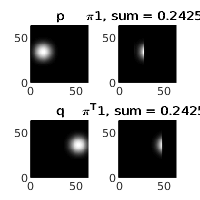

-----------------------------


Meta: sigma = 5, filter_size = 41


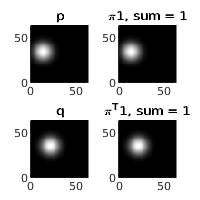

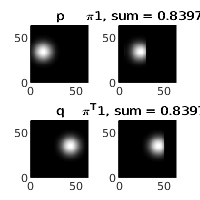

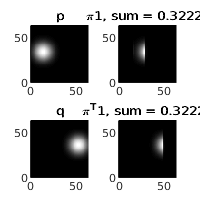

-----------------------------


Meta: sigma = 1, filter_size = 45


-----------------------------


Meta: sigma = 2.5, filter_size = 45


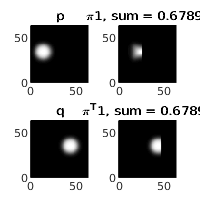

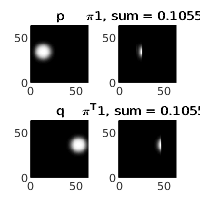

-----------------------------


Meta: sigma = 4.1, filter_size = 45


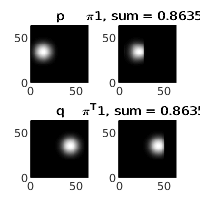

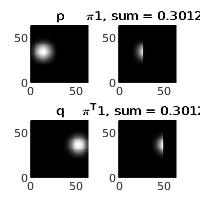

-----------------------------


Meta: sigma = 5, filter_size = 45


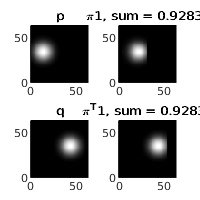

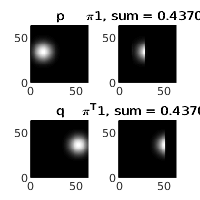

-----------------------------


Meta: sigma = 1, filter_size = 101


-----------------------------


Meta: sigma = 2.5, filter_size = 101


-----------------------------


Meta: sigma = 4.1, filter_size = 101


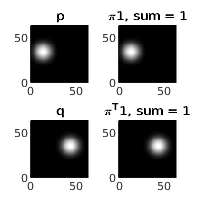

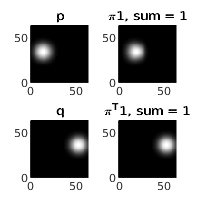

-----------------------------


Meta: sigma = 5, filter_size = 101


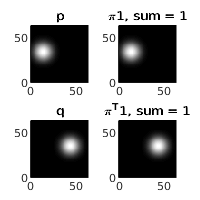

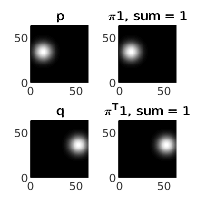


format long g

imgs = {
         im2double(rgb2gray(imread('images/one-blob.png')))
         im2double(rgb2gray(imread('images/one-blob-moved.png')))
         im2double(rgb2gray(imread('images/one-blob-moved-even-more.png')))
         im2double(rgb2gray(imread('images/one-blob-moved-even-more-again.png')))
};



for filter_size=filter_sizes
    for sigma=sigmas
        disp('-----------------------------')
        disp("Meta: sigma = "+sigma+", filter_size = "+filter_size)
        
        dists = {
                make_dist(imgs{1}),
                make_dist(imgs{2}),
                make_dist(imgs{3}),
                make_dist(imgs{4})
            };
        
        for i = 2:4
            figure('Position', [0, 0, 200, 200]);
            colormap('gray')
            
            subplot(2,2,1)
            hold on
            axis equal
            axis([0, 64, 0, 64])
            imagesc(dists{1})
            title('p')
        
            [wd,v,w] = Sinkhorn(dists{1},dists{i});
            ed = sqrt(sum(  (dists{1}(:) - dists{i}(:)).^2  ));
            subplot(2,2,3)
            hold on
            axis equal
            axis([0, 64, 0, 64])
            imagesc(dists{i})
            title('q')
        %     title("W2 = " + wd + ", D2 = " + ed)
            
            img = SinkhornEvalR(v,w,ones(size(v,1),size(v,2)));
            subplot(2,2,2)
            hold on
            axis equal
            axis([0, 64, 0, 64])
            imagesc(img)
        %     title('\pi1')
            title("\pi1, sum = " + sum(img(:)))
            
            img = SinkhornEvalL(v,w,ones(size(v,1),size(v,2)));
            subplot(2,2,4)
            hold on
            axis equal
            axis([0, 64, 0, 64])
            imagesc(img)
        %     title('\pi^T1')
            title("\pi^T1, sum = " + sum(img(:)))
            
            if enable_prints
                for type = print_types
                    print("prints/delta-comparison-with-marginals-"+sigma+"-sigma-"+filter_size+"-filter-size-"+i+type{1}{2},type{1}{1})
                end
            end
        end
    end
end

## Coupling Test #2

-----------------------------


Meta: sigma = 1, filter_size = 5


Wasserstein distance = 1196.6214


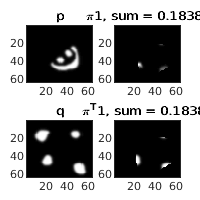

-----------------------------


Meta: sigma = 2.5, filter_size = 5


Wasserstein distance = 2915.741


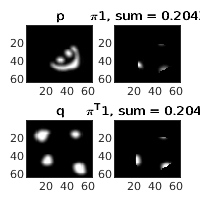

-----------------------------


Meta: sigma = 4.1, filter_size = 5


Wasserstein distance = 4764.4458


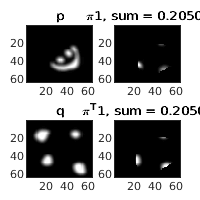

-----------------------------


Meta: sigma = 5, filter_size = 5


Wasserstein distance = 5806.2414


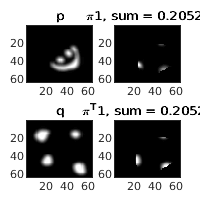

-----------------------------


Meta: sigma = 1, filter_size = 41


Wasserstein distance = 590.6116


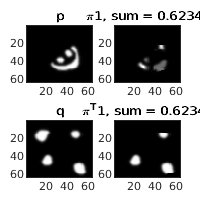

-----------------------------


Meta: sigma = 2.5, filter_size = 41


Wasserstein distance = 85.5185


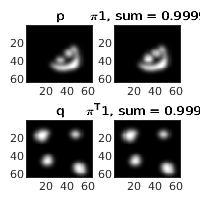

-----------------------------


Meta: sigma = 4.1, filter_size = 41


Wasserstein distance = 31.7843


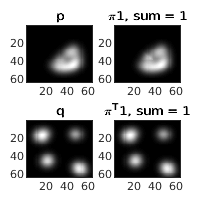

-----------------------------


Meta: sigma = 5, filter_size = 41


Wasserstein distance = 9.2301


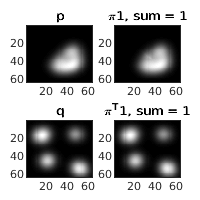

-----------------------------


Meta: sigma = 1, filter_size = 45


Wasserstein distance = 590.6116


-----------------------------


Meta: sigma = 2.5, filter_size = 45


Wasserstein distance = 62.188


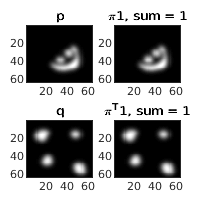

-----------------------------


Meta: sigma = 4.1, filter_size = 45


Wasserstein distance = 14.084


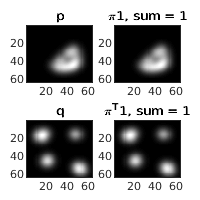

-----------------------------


Meta: sigma = 5, filter_size = 45


Wasserstein distance = -1.7082


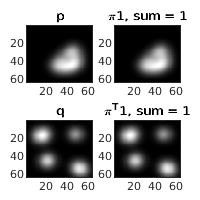

-----------------------------


Meta: sigma = 1, filter_size = 101


Wasserstein distance = 590.6116


-----------------------------


Meta: sigma = 2.5, filter_size = 101


Wasserstein distance = 62.188


-----------------------------


Meta: sigma = 4.1, filter_size = 101


Wasserstein distance = 12.4325


-----------------------------


Meta: sigma = 5, filter_size = 101


Wasserstein distance = -3.5752



format long g

im1 = im2double(rgb2gray(imread('images/smile_s.png')));
im2 = im2double(rgb2gray(imread('images/dots_s.png')));

for filter_size=filter_sizes
    for sigma=sigmas
        disp('-----------------------------')
        disp("Meta: sigma = "+sigma+", filter_size = "+filter_size)
        
        dist1 = make_dist(im1);
        dist2 = make_dist(im2);
        
        [wd,v,w] = Sinkhorn(dist1, dist2);
        disp("Wasserstein distance = " + wd)
        
        figure()
        figure('Position', [0, 0, 200, 200]);
        colormap('gray')
            
        hold on
        subplot(2,2,1);
        axis equal
        axis([0 64 0 64])
        imagesc(dist1)
        title("p")
        
        subplot(2,2,3);
        axis equal
        axis([0 64 0 64])
        imagesc(dist2)
        title("q")
        
        img = SinkhornEvalR(v,w,ones(size(v,1),size(v,2)));
        subplot(2,2,2);
        axis equal
        
        axis([0 64 0 64])
        imagesc(img)
        title("\pi1, sum = " + sum(img(:)))
        
        img = SinkhornEvalL(v,w,ones(size(v,1),size(v,2)));
        subplot(2,2,4)
        axis equal
        axis([0 64 0 64])
        imagesc(img)
        title("\pi^T1, sum = " + sum(img(:)))
        
        if enable_prints
            for type = print_types
                print("prints/smiley-comparison-"+sigma+"-sigma-"+filter_size+"-filter-size-with-marginals"+type{1}{2},type{1}{1})
            end
        end
    end
end

## Coupling Test #3


format long g

dist1 = make_dist(im2double(rgb2gray(imread('images/dots_s.png'))));
dist2 = make_dist(im2double(rgb2gray(imread('images/smile_s.png'))));

disp('-----------------------------')
[wd,v,w] = Sinkhorn(dist1, dist2);
disp("Wasserstein distance = " + wd)

p = [
    linspace(35,35,64)
    1:64
];
mask = ones(size(v,1), size(v,2));
% b = boxes(size(v,1), size(v,2));
% mask = b{1};
% mask = zeros(size(v,1), size(v,2));
% mask(sub2ind(size(mask), p(1,:), p(2,:))) = 1;
img = SinkhornEvalL(v,w,mask);
composition = [mask img];
composition = composition > 0;


dists = [dist1 dist2];
figure()
hold on
axis equal
imagesc([dist1.*mask img])

figure()
hold on
axis equal
imagesc([dist1 dist2])


## Quadrant test


format long g

dist1 = make_dist(im2double(rgb2gray(imread('images/smile_s.png'))));
dist2 = make_dist(im2double(rgb2gray(imread('images/dots_s.png'))));


% figure()
% hold on
% axis equal
% imshowpair(imcomplement(imresize(imread('images/dots_s.png'),2)),imcomplement(imresize(imread('images/smile_s.png'),2)), 'montage')

[wd,v,w] = Sinkhorn(dist1, dist2);
disp('---------------------------------------')
disp("Wasserstein distance = " + wd)

img_out = zeros(size(dist1,1),size(dist1,2),4);
cmp_out = zeros(size(dist1,1),size(dist1,2),4);
s = 0;
for b = boxes(size(dist1,1), size(dist1,2));
    
    b = b{1};
    
    % Get random color
    color = randn(1,3);
    color = color .* color;
    color = color / max(color);
    
    img = SinkhornEvalR(v,w,b);
    s = s + sum(img(:));
    col_img = zeros(size(img,1), size(img,2), 3);
    
    alpha = minv(img(1:size(img,1),1:size(img,2)) / 0.002, 1.0);
    col_img(1:size(img,1),1:size(img,2),1) = color(1) * alpha;
    col_img(1:size(img,1),1:size(img,2),2) = color(2) * alpha;
    col_img(1:size(img,1),1:size(img,2),3) = color(3) * alpha;
    col_img(1:size(img,1),1:size(img,2),4) = alpha;
    
    mask = img_out(:,:,4) < alpha;
    img_out(mask(:,:,[1,1,1,1])) = col_img(mask(:,:,[1,1,1,1]));
    
    cmp_tmp = b .* dist2;
    cmp_img = zeros(size(cmp_tmp,1), size(cmp_tmp,2), 3);
    alpha = minv(cmp_tmp(1:size(cmp_tmp,1),1:size(cmp_tmp,2)) / 0.002, 1.0);
    cmp_img(1:size(cmp_tmp,1),1:size(cmp_tmp,2),1) = color(1) * alpha;
    cmp_img(1:size(cmp_tmp,1),1:size(cmp_tmp,2),2) = color(2) * alpha;
    cmp_img(1:size(cmp_tmp,1),1:size(cmp_tmp,2),3) = color(3) * alpha;
    cmp_img(1:size(cmp_tmp,1),1:size(cmp_tmp,2),4) = alpha;
    
    mask = cmp_out(:,:,4) < alpha;
    cmp_out(mask(:,:,[1,1,1,1])) = cmp_img(mask(:,:,[1,1,1,1]));
    
    
end

disp("Marginal sum = " + s)

figure()
hold on
axis equal
imshowpair(imcomplement(imresize(cmp_out(:,:,1:3),2)),imcomplement(imresize(img_out(:,:,1:3),2)), 'montage')

if enable_prints
    for type = print_types
        print("prints/quadrant-test-"+sigma+"-sigma-"+filter_size+"-filter-size"+type{1}{2}, type{1}{1})
    end
end









